# Descarga completa

#### Init

clear all;
clf;
clc;

p_colour = [0.8500, 0.3250, 0.0980];
R0 = 0.0151;
R1 = 0.1199;
C1 = 1.7817e+04;

## Original

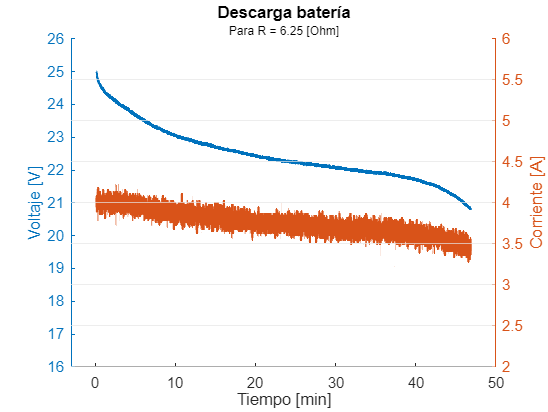

data = readmatrix("2025-12-22_Battery_3/Muestras_arduino.csv", 'NumHeaderLines', 2);
time_11      = data(:, 1);
time_11      = time_11/(1000*60);
volt_11      = data(:, 2);
ampere_11    = data(:, 3);

%Recorte
time_11      = time_11(1:11000);
volt_11      = volt_11(1:11000);
ampere_11      = ampere_11(1:11000);

clf %% clean figure

figure(5)
hold on 
yyaxis left
plot(time_11,volt_11,'LineStyle', '-', 'LineWidth', 1.5)
ylim([16 26]);
ylabel("Voltaje [V]");

yyaxis right

plot(time_11,ampere_11,'LineStyle', '-', 'LineWidth', 1.5)
ylim([2 6]);
ylabel("Corriente [A]");

% This effectively brings the "Left" side to the top layer
xlabel("Tiempo [min]");
xlim([-3 50])
title("Descarga batería");
subtitle("Para R = 6.25 [Ohm]",'FontSize',8);

grid off; % Turn off the default "left-aligned" grid

% Get the tick positions of the right axis
ticks = get(gca, 'YTick');

% Draw horizontal lines at every tick mark
% 'HandleVisibility','off' ensures these don't show up in a legend
yline(ticks, 'Color', [0.9 0.9 0.9], 'LineWidth', 0.5, 'HandleVisibility', 'off');

hold off


%%%exportgraphics(gcf,"Figuras/bat_dsg_0.png");

## Descarga batería (corriente media)

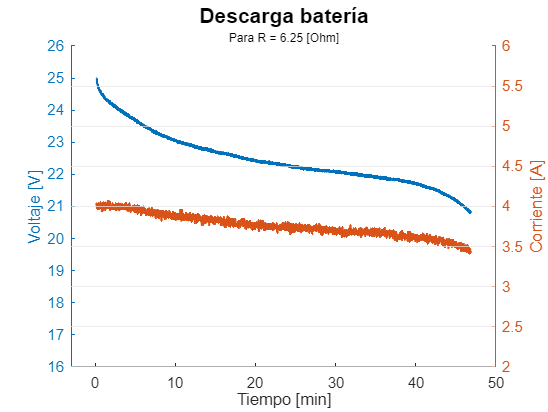

data = readmatrix("2025-12-22_Battery_3/Muestras_arduino.csv", 'NumHeaderLines', 2);
time_12      = data(:, 1);
time_12      = time_12/(1000*60);
volt_12      = data(:, 2);
ampere_12    = data(:, 3);
ampere_12    = movmean(ampere_12,8);

%recorte
time_12      = time_12(1:11000);
volt_12      = volt_12(1:11000);
ampere_12      = ampere_12(1:11000);

clf %% clean figure
figure(1)
hold on 
grid on
yyaxis left
plot(time_12,volt_12,'LineStyle', '-', 'LineWidth', 1.5)
ylim([16 26]);
ylabel("Voltaje [V]");

yyaxis right
plot(time_12,ampere_12,'LineStyle', '-', 'LineWidth', 1.5)
ylim([2 6]);
ylabel("Corriente [A]");

% This effectively brings the "Left" side to the top layer
xlabel("Tiempo [min]");
xlim([-3 50])
title("Descarga batería",'FontSize',14);
subtitle("Para R = 6.25 [Ohm]",'FontSize',8);

grid off; % Turn off the default "left-aligned" grid

% Get the tick positions of the right axis
ticks = get(gca, 'YTick');

% Draw horizontal lines at every tick mark
% 'HandleVisibility','off' ensures these don't show up in a legend
yline(ticks, 'Color', [0.9 0.9 0.9], 'LineWidth', 0.5, 'HandleVisibility', 'off');

hold off
exportgraphics(gcf,"Figuras/bat_dsg.png");

## Descarga batería (SoC... Wh, mAh)

clear pwr_1 chg_1 chg_2

for i = 1:(11000-1)
    m_ampere(i) = mean([ampere_12(i+1) ampere_12(i)]);
    m_volt(i) = mean([volt_12(i+1) volt_12(i)]);
    pwr_1(i) =  m_ampere(i) * m_volt(i);

    if i == 1
        chg_1(i) = 0;
        chg_2(i) = 0;
        continue
    end
    chg_1(i) = chg_1(i-1) + m_ampere(i) * ((time_12(i+1) - time_12(i)) *1000 / 60);
    chg_2(i) = chg_2(i-1) + pwr_1(i) * ((time_12(i+1) - time_12(i)) / 60);
end
chg_1 = [chg_1 chg_1(end)]; %Ah
chg_2 = [chg_2 chg_2(end)]; %Wh
pwr_1 = [pwr_1 pwr_1(end)];

chg_total = chg_1(end)

chg_total = 2.9243e+03

#### DoD, SoC

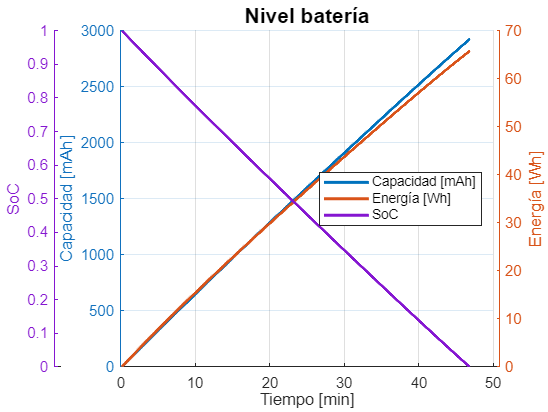

DoD = chg_1 / chg_total;
SoC = 1 - DoD;

cPurp = [0.5210 0.0860 0.8190];
chg = [chg_1; chg_2; SoC];

clf;
hold  on
grid on
plot(time_12   ,chg(1,:),'LineWidth', 2)
addaxis(time_12,chg(2,:),'LineWidth', 2);
addaxis(time_12,chg(3,:),'LineWidth', 2, 'Color', cPurp);
ylabels = {'Capacidad [mAh]','Energía [Wh]','SoC'};
xlabel('Tiempo [min]');

ax = gca;
c = ax.YColor;
ax.YColor = [0.0660 0.4430 0.7450];

hax = getaddaxisdata(gca,'axisdata');
hax = [hax{:}];
hax = [gca hax(1,:)];
x0 = 0.1; % spacing between outermost rulers and figure edge
xgap = 0.12; % spacing between rulers
fontsize = 10; % base font size for all rulers/labels
% get info about ruler locations
nlr = nnz(strcmp({hax.YAxisLocation},'left'));
nrr = numel(hax) - nlr;
% calculate x-offsets for rulers, reorder to match axes order
xposl = x0+(0:nlr-1)*xgap;
xposr = 1-(x0+(nrr-1:-1:0)*xgap);
xpos = zeros(1,numel(hax));
xpos(1:2:nlr*2) = fliplr(xposl);
xpos(2:2:nrr*2) = xposr;
% width of primary axes
wax = 1 - ((nlr-1)+(nrr-1))*xgap - 2*x0;
% apply properties
for k = 1:numel(hax)
    hax(k).Position(1) = xpos(k);
    hax(k).YLabel.String = ylabels{k};
    hax(k).FontSize = fontsize;
end
hax(1).Position(3) = wax;
title('Nivel batería', 'FontSize', 14);
legend(ylabels,'Location','east')

hold off
exportgraphics(gcf,"Figuras/bat_soc.png");

### Ir bate

tau = 1/(R1 * C1);
for i = 1:(11000)   
    if i == 1
        ir1(i) = 4;
        continue
    end
    m_ampere(i) = mean([ampere_12(i) ampere_12(i-1)]);
    dt(i) = (time_12(i) - time_12(i-1));

    ir1(i) = ir1(i-1)*exp(-dt(i)/tau) + m_ampere(i-1)*(1-(exp(-dt(i)/tau)));
end
% ir1 = [ir1 ir1(end)]; %A (r1)



$$I_{R1}[k+1] = exp ( -\frac{\Delta t}{R_1\cdot C_1}) I_{R1}[k] + (1 -exp(-\frac{\Delta t}{R_1\cdot C_1})) I_{bat}[k]$$



% clf
% figure(3)
% hold on 
% yyaxis left
% plot(time_12,volt_12,'LineStyle', '-', 'LineWidth', 1.5)
% % ylim([16 26]);
% ylabel("Voltaje [V]");
% 
% yyaxis right
% plot(time_12,ir1,'LineStyle', '-', 'LineWidth', 1.5)
% % ylim([2 6]);
% % ylabel("powa [W]");
% % ylabel("capacidad [wh]");
% ylabel("amp (r1) [A]");
% 
% % This effectively brings the "Left" side to the top layer
% xlabel("Tiempo [min]");
% % title("Descarga batería");
% % subtitle("Para R = 6.25 [Ohm] constante",'FontSize',8);
% hold off

% clf
% figure(3)
% hold on 
% yyaxis left
% plot(time_12,ir1,'LineStyle', '-', 'LineWidth', 1.5)
% ylim([3.4 4.1]);
% ylabel("Voltaje [V]");
% 
% yyaxis right
% plot(time_12,ampere_12,'LineStyle', '-', 'LineWidth', 1.5, 'Color', 'red')
% ylim([3.4 4.1]);
% % ylabel("powa [W]");
% % ylabel("capacidad [wh]");
% ylabel("amp (r1) [A]");
% 
% % This effectively brings the "Left" side to the top layer
% xlabel("Tiempo [min]");
% % title("Descarga batería");
% % subtitle("Para R = 6.25 [Ohm] constante",'FontSize',8);
% hold off


### OCV(SOC(k))

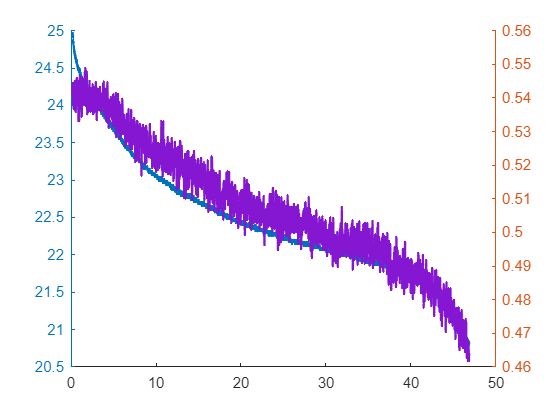

for i = 1:11000
    OCV(i) = volt_12(i) + R1*ir1(i) + R0*ampere_12(i);
    diff_v(i) = OCV(i) - volt_12(i);
end

figure(9)
hold on
yyaxis left
plot(time_12,volt_12,'LineStyle', '-', 'LineWidth', 1.5)
yyaxis right
plot(time_12,diff_v,    'LineStyle', '-', 'LineWidth', 1.5, 'Color', cPurp)
hold off

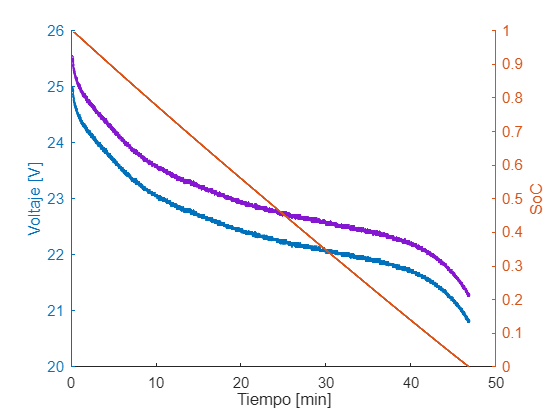


clf
figure(3)
hold on 
yyaxis left
plot(time_12,volt_12,'LineStyle', '-', 'LineWidth', 1.5)
plot(time_12,OCV,    'LineStyle', '-', 'LineWidth', 1.5, 'Color', cPurp)
ylim([20 26]);
ylabel("Voltaje [V]");

yyaxis right
plot(time_12,SoC,    'LineStyle', '-', 'LineWidth', 1.5)
% ylabel("powa [W]");
ylabel("SoC");

% This effectively brings the "Left" side to the top layer
xlabel("Tiempo [min]");
% title("Descarga batería");
hold off

### SoC(k)

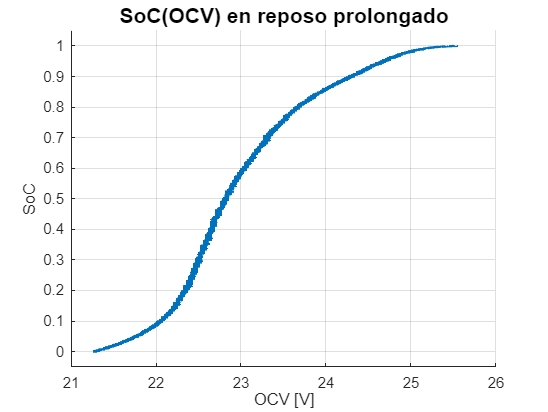

% figure(11)
% % plot(SoC,OCV,'LineStyle', '-', 'LineWidth', 1.5)
% ylabel("OCV [V]");
% xlabel("SoC");
% title("Descarga batería");
clf
figure(12)
hold on
grid on
plot(OCV,SoC,'LineStyle', '-', 'LineWidth', 1.5)
ylim([-0.05 1.05]);
ylabel("SoC");
xlabel("OCV [V]");
title("SoC(OCV) en reposo prolongado", 'FontSize', 14);
hold off

exportgraphics(gcf,"Figuras/bat_ocv.png");